# Integrator Lab: Solving First Order ODEs in MATLAB and Picard Approximation

This lab will teach you to numerically solve first order ODEs using a built in MATLAB integrator, `ode45`.  `ode45` is a good, general purpose tool for integrating first order equations (and first order systems). It is not always the right algorithm, but it is usually the right algorithm to try first. This lab will also teach you how to manipulate symbolic functions in MATLAB.

You will learn how to use the `ode45` routine, how to interpolate between points, and how MATLAB handles data structures. You will also learn how to use MATLAB for exact symbolic calculations and write your own Picard approximation code.

Opening the m-file lab2.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are eight exercises in this lab that are to be handed in at the end of the lab. Write your solutions in the template, including appropriate descriptions in each step. Save the .m file and submit it online using Quercus.

## Student Information

Student Name: Qixian Aiden Wang

Student Number: 1008880169

## Set up an inline function representation of an ODE and solve it

MATLAB has many built in routines for solving differential equations of the form

`y' = f(t,y)`

We will solve them using `ode45`, a high precision integrator. To do this, we will need to construct an inline function representation of `f`, an initial condition, and specify how far we want MATLAB to integrate the problem. Once we have set these, we pass the information to `ode45` to get the solution.

For a first example, we will solve the initial value problem

`y' = y, y(0) = 1`

which has as its answer `y = e^t`. 

% Set up the right hand side of the ODE as an inline function
f = @(t,y) y; 

% The initial conditions
t0 = 0;
y0 = 1;

% The time we will integrate until
t1 = 2;

soln = ode45(f, [t0, t1], y0);

## Examining the output

When we execute the `ode45`, it returns a data structure, stored in soln. We can see the pieces of the data structure with a display command:

disp(soln);

## Understanding the components of the solution data structure

The most important elements of the data structure are stored in the `x` and `y` components of the structure; these are vectors. Vectors `x` and `y` contain the points at which the numerical approximation to the initial vlaue problem has been computed. In other words, `y(j)` is the approximate value of the solution at `x(j)`.

**NOTE:** Even though we may be studying a problem like `u(t)` or `y(t)`, MATLAB will always use `x` for the independent variable and `y` for the dependent variable in the data structure.

Pieces of the data structure can be accessed using a period, as in C/C++ or Java. See the examples below:

% Display the values of |t| at which |y(t)| is approximated
fprintf(' Vector of t values: ');
disp(soln.x);
% Display the the corresponding approximatations of |y(t)|
fprintf(' Vector of y values: ');
disp(soln.y);

% Display the approximation of the solution at the 3rd point:
fprintf(' Third element of the vector of t values: %g\n',soln.x(3));
fprintf(' Third element of the vector of y values: %g\n',soln.y(3));

## Visualizing and comparing the solution

We can now visualize the solution at the computed data points and compare with the exact solution.

% Construct the exact solution
tt = linspace(0,2,50);
yy = exp(tt);

% Plot both on the same figure, plotting the approximation with x's
plot(tt, yy, soln.x, soln.y, 'x', 'MarkerSize',10, 'LineWidth', 2);
% NOTE: the MarkerSize and LineWidth are larger than their defaults of 6
% and 1, respectively.  This makes the print out more readable.

% Add a label to the axis and a legend
xlabel('t');
legend('Exact', 'Numerical','Location','Best');

## Exercise 1

Objective: Solve an initial value problem and plot both the numerical approximation and the corresponding exact solution.

Details: Solve the IVP

`y' = y tan t + sin t, y(0) = -1/2`

from `t = 0` to `t = pi`.

Compute the exact solution (by hand), and plot both on the same figure for comparison, as above.

Your submission should show the construction of the inline function, the use of ode45 to obtain the solution, a construction of the exact solution, and a plot showing both. In the comments, include the exact solution.

Label your axes and include a legend.

% Define the function
f = @(t,y) y * tan(t) + sin(t);

% Initial Condition
t0 = 0; y0 = -0.5;
% Time integrate until
t1 = pi;
%ode45
soln = ode45(f, [t0, t1], y0);

%Exact Solution
t = linspace(0, pi, 100);
y = ((sin(t).^2) - 1) ./ (2 .* cos(t));

%Plot both graph on 1 figure
plot(t, y, soln.x, soln.y, 'x', 'MarkerSize',10, 'LineWidth', 2);

%Label graph
xlabel('t');
ylabel('y');
legend('Exact', 'Numerical','Location','Best');

## Computing an approximation at a specific point

As you should be able to see by examining `soln.x`, ode45 returns the solution at a number of points between `t0` and `t1`. But sometimes we want to know the solution at some intermediate point.

To obtain this value, we need to interpolate it in a consistent way. Fortunately, MATLAB provides a convenient function, `deval`, specifically for this.

% Compute the solution at t = .25:
deval(soln, .25)

% Compute the solution at t = 1.6753:
fprintf(' Solution at 1.6753: %g\n', deval(soln, 1.6753));

% Compute the solution at 10 grid points between .45 and 1.65:
tinterp = linspace(.45, 1.65, 10);
deval(soln, tinterp)

% Alternatively:
deval(soln, linspace(.45, 1.65, 10))

## Exercise 2

Objective: Interpolate a solution at a number of grid points

Details: For the solution you computed in exercise 1, use deval to compute the interpolated values at 10 grid points between 2 and 3.

% Compute the solution at 10 grid points between 2 and 3:
tinterp = linspace(2, 3, 10);
deval(soln, tinterp)

## Errors, Step Sizes, and Tolerances

As you may have noticed, in contrast to the IODE software, at no point do we set a step size for our solution. Indeed, the step size is set adaptively to conform to a specified error tolerance. 

Roughly speaking, given the solution at `(t_j, y_j)`, `ode45` computes two approximations of the solution at `t_{j+1} = t_j + h`; one is of greater accuracy than the other. If the difference is below a specified tolerance, the step is accepted and we continue. Otherwise the step is rejected and the smaller step size, `h`, is used; it is often halved.

We can compute the global truncation error at each solution point, figure out the maximum error, and visualize this error (on a linear-log scale):

% Compute the exact solution
yexact = exp(soln.x);

% Compute the pointwise error; note the use of MATLAB's vectorization
err = abs(yexact - soln.y);

disp(err);

fprintf('maximum error: %g \n', max(err));

semilogy(soln.x, err, 'LineWidth', 2);
xlabel('t');
ylabel('error');

## Exercise 3

Objective: Examine the error of a solution generated by `ode45`

Details: For your solution to exercise 1, compute the pointwise error, identify the maximum value of the error, and visualize the error on a linear-log plot (use semilogy to plot the log of the error vs. t). Write in the comments where the error is largest, and give a brief (1-2 sentences) explanation of why it is largest there. Make sure to label your axes.

% Compute the exact solution
yexact = ((sin(soln.x).^2) - 1) ./ (2 .* cos(soln.x));

% Compute the pointwise error
err = abs(yexact - soln.y);

fprintf('max error: %g \n', max(err));

%Plot with semilogy
semilogy(soln.x, err, 'LineWidth', 2);

%Label Axis
xlabel('t');
ylabel('error');

%The max error occurs at ~t=1.5s or pi/2. Because this is an inflection
%point of the solution, so the rate of change of the derivative
%is at maximum when t=1.5s, thus, a max error can easily occur.

## Exercise 4

Objective: Solve and visualize a nonlinear ode using ode45

Details: Solve the IVP

`y' = 1 / y^2 , y(1) = 1`

from `t=1` to `t=10` using `ode45`. Find the exact solution and compute the maximum pointwise error. Then plot the approximate solution and the exact solution on the same axes.

Your solution should show the definition of the inline function, the computation of its solution in this interval, the computation of the exact solution at the computed grid points, the computation of the maximum error, and a plot of the exact and approximate solutions.

%Your axes should be appropriately labeled and include a legend.

%Define the function
f = @(t,y) 1 / y^2; 

%Init conditions
t0 = 1; y0 = 1;

%Time to integrate until
t1 = 10;

%ode45
soln = ode45(f, [t0, t1], y0);

%Exact solution: y = (3x-2)^(1/3)
t = linspace(1, 10, 50);
y = (3 .* t - 2) .^ (1/3);

% Plot both on the same figure
plot(t, y, soln.x, soln.y, 'x', 'MarkerSize', 10, 'LineWidth', 2);

%Label the graph
xlabel('t');
ylabel('y');
legend('Exact', 'Numerical','Location','Best');

% Compute the exact solution
yexact = (3.*soln.x-2).^(1/3);

% Compute the pointwise error
err = abs(yexact - soln.y);

disp(err);

fprintf('maximum error: %g \n', max(err));

## Exercise 5

Objective: Solve and visualize an ODE that cannot be solved by hand with `ode45`.

Details: Solve the IVP

`y' = 1 - t y / 2, y(0) = -1`

from `t=0` to `t=10`. 

Your solution should show you defining the inline function, computing the solution in this interval, and plotting it.

Your axes should be appropriately labeled

%Define the function
f = @(t, y) 1 - t .* y / 2;

%Init conditions
t0 = 0; t1 = 10;
y1 = -1;

%ode45 solution
soln = ode45(f, [t0,t1], y1);

%Plot and label the graph
plot(soln.x, soln.y, 'x', 'MarkerSize',10, 'LineWidth', 2);
xlabel('t'); 
ylabel('y');
title('Exercise 5');

## Exercise 6 - When things go wrong

Objective: Solve an ode and explain the warning message

Details: Solve the IVP:

`y' = y^3 - t^2, y(0) = 1`

from `t=0` to `t=1`. 

Your solution should show you defining the inline function, and computing the solution in this interval.

If you try to plot the solution, you should find that the solution does not make it all the way to t = 1.

In the comments explain why MATLAB generates the warning message that you may see, or fails to integrate all the way to t=1. HINT: Try plotting the direction field for this with IODE.

%Define the function
f = @(t,y) y.^3 - t.^2;

%Init conditions
t0 = 0; y1 = 1;
t1 = 1;

%ode45 solution
soln = ode45(f, [t0,t1], y1);

%Plot and label the graph
plot(soln.x, soln.y, 'x', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('t'); 
ylabel('y');
title('Exercise 6');

%There's warning msgs because as t increases, the slope becomes
%infinity before t reaches t1 = 1s. Since the slope is reaching
%inifnity, it is impossible for the approximation to happen.

## Using symbolic variables to define functions

We can define symbolic variables to let MATLAB know that these variables will be used for exact computations

% Start by defining the variables as symbolic
syms t s x y

% Define a function by simply writing its expression

f = cos(t)
g = sin(t)
h = exp(2*x)

% We can manipulate these functions

simplify(f^2+g^2)
diff(h)

% We can plot a function defined symbolically using the command |ezplot|.
% Learn about the command |ezplot|:

help ezplot

% Plot the function |f(t)| and |h(x)|

ezplot(f)
ezplot(h)

If we try to evaluate the function `f(0)`, we get an error message. 

The symbolic variables are not meant to be used to evaluate functions, but to manipulate functions, compute derivatives, etc. To evaluate a function using symbolic variables is a little cumbersome:

% We need to substitute the variable by a value:

subs(f,t,pi)

This expression means: In the expression `f`, substitute the variable `t` by the number `pi`.

% If we use a value where the cosine does not have a "nice" expression, we
% need to approximate the result:

subs(f,t,2)

% We need to use the command |eval|

eval(subs(f,t,2))

## Exercise 7

Objective: Define a function using symbolic variables and manipulate it.

Details: Define the function `f(x) = sin(x)cos(x)`

Use MATLAB commands to obtain a simpler form of this function, compute value of this function for `x=pi/4` and `x=1`, and plot its graph.

syms x

f = sin(x) * cos(x);

simplify(f)

$$ans = \frac{\sin\left(2\,x\right)}{2}$$

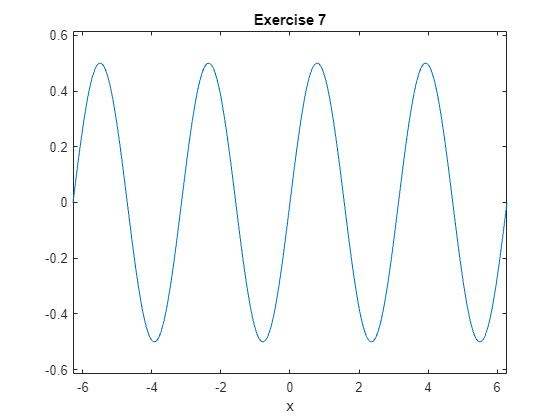


ezplot(f);

title('Exercise 7');

fprintf('f(x = pi/4) = %g\n',eval(subs(f,x,pi/4)))

f(x = pi/4) = 0.5


fprintf('f(x = 1) is %g\n',eval(subs(f,x,1)))

f(x = 1) is 0.454649


## Obtaining Picard approximations

Consider an initial value problem

`y' = 1 + y` `y(0) = 0`

First we need to define the variables we will be using

syms t s y;

% We then need to define the function f

f = 1+y; % we define it without the @(t,y) because it is a symbolic function

% We set up our initial approximation phi_0 = 0:

phi=[sym(0)];   % we will keep a list with all the approximations

% Set up a loop to get successive approximations using Picard iterations

N=5;

for i = 1:N
    func=subs(f,y,phi(i));    % prepare function to integrate: y -> previous phi
    func=subs(func,t,s);      % variable of integration is s, so we need to change
                              % t -> s
    
    newphi = int(func, s, 0 ,t);   % integrate to find next approximation
    
    phi=cat(2,phi,[newphi]);       % update the list of approximations by adding new phi
end

% Show the last approximation

phi(N+1)

% Plot the approximation just found

picard=ezplot(phi(N+1),[0,5]);
set(picard,'Color','green');         % set the color of the graph to green

% In this case, the exact solution is
%
% |y=e^t-1|
%
% Compare the approximation and the exact solutions

hold on;
exact=ezplot(exp(t)-1,[0,5]);

xlabel('t');
ylabel('y');
title('Picard Approximations');
legend('Picard Approximation', 'Exact Solution','Location','NorthWest');

## Exercise 8

Find the Picard approximation phi_5. For better efficiency, do not keep all the previous approximations.

Compute the exact solution (by hand), and plot both on the same figure for comparison, as above.

Label your axes and include a legend.

HINT. The initial condition has 1 instead of 0, so the Picard method needs to be adapted.

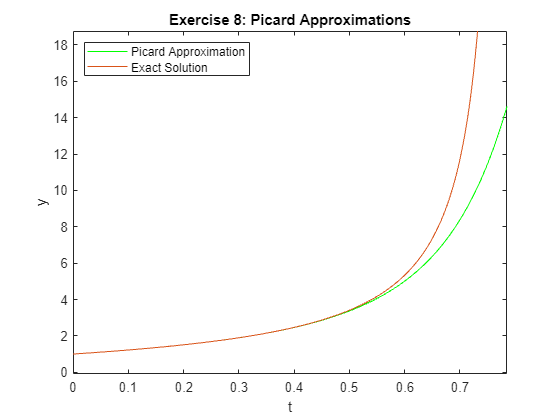

syms t s y;

% We then need to define the function f

f = 1 + y.^2; % we define it without the @(t,y) because it is a symbolic function

% We set up our initial approximation phi_0 = 1:

phi = [sym(1)];   % we will keep a list with all the approximations

% Set up a loop to get successive approximations using Picard iterations

N = 5;

for i = 1:N
    func = subs(f,y,phi(i));    % prepare function to integrate: y -> previous phi
    func = subs(func,t,s);      % variable of integration is s, so we need to change
                              % t -> s
    newphi = int(func, s, 0 ,t) + 1;   % integrate to find next approximation
    
    phi = cat(2,phi,[newphi]);       % update the list of approximations by adding new phi
end

% Plot the approximation just found

picard = ezplot(phi(N+1),[0,5]);
set(picard,'Color','green');         % set the color of the graph to green

% In this case, the exact solution is
%
% |y=tan(t+pi/4)|
%
% Compare the approximation and the exact solutions

hold on;
exact = ezplot(tan(t+pi/4),[0,pi/4]);

xlabel('t');
ylabel('y');
title('Exercise 8: Picard Approximations');
legend('Picard Approximation', 'Exact Solution','Location','NorthWest');